# Example: Dispersion Curves - Teflon Plate

This example follows the same format as: Example: Dispersion Curves - Titanium Plate.

## Initialize an ElasticMatrix Object

Initialize an ElasticMatrix object with a Medium object.

% A titanium plate:
my_medium = Medium('vacuum', 0, 'teflon', 0.001, 'vacuum', 1);

% Initialize the object:
my_model = ElasticMatrix(my_medium);

## Setting Calculation Parameters

Set a range of frequencies:

my_model.setFrequency(linspace(0.1e6, 2e6, 2)); % [Hz]

## Calculating Dispersion Curves

Calculate the dispersion curves:

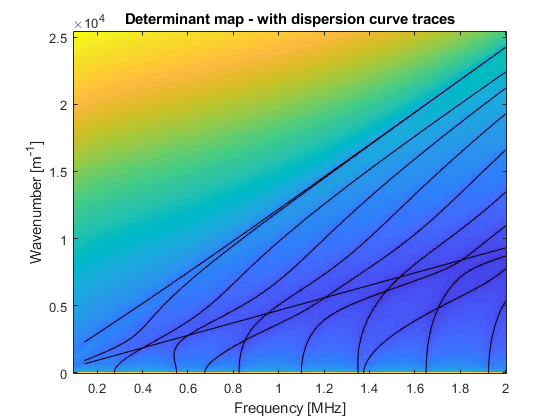

... calculating dispersion curves ...
... finished calculating dispersion curves ...


my_model.calculateDispersionCurves;

## Plotting Dispersion Curves

The dispersion curves can be plotted using the .plotDispersionCurves method. Note: the algorithm will occasionally identify the critical angle as a dispersion curve.

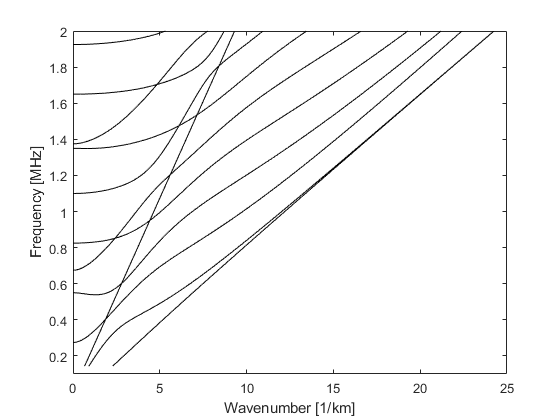

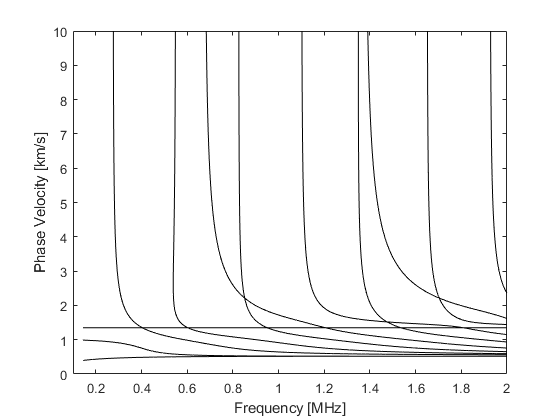

figure_handles = my_model.plotDispersionCurves;


% The data from a teflon plate calculation in Disperse is added:

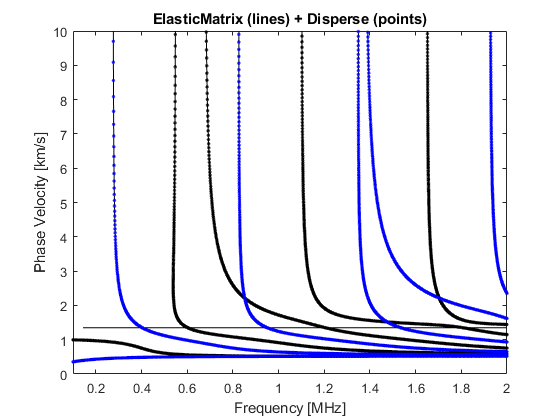

disperse_data = importdata('disperseTeflonPlateData.txt');

% Plot disperse points:
figure(figure_handles.fig2)
% figure

% S0
hold on
plot(disperse_data.data(:, 1), disperse_data.data(:, 2), 'k.')

% A0
plot(disperse_data.data(:, 3), disperse_data.data(:, 4), 'b.')


% S1
plot(disperse_data.data(:, 5), disperse_data.data(:, 6), 'k.')

% S2
plot(disperse_data.data(:, 7), disperse_data.data(:, 8), 'k.')

% S3
plot(disperse_data.data(:, 9), disperse_data.data(:, 10), 'k.')

% S4
plot(disperse_data.data(:, 11), disperse_data.data(:, 12), 'k.')

% S5
plot(disperse_data.data(:, 13), disperse_data.data(:, 14), 'k.')


% A1
plot(disperse_data.data(:, 13), disperse_data.data(:, 14), 'b.')

% A2
plot(disperse_data.data(:, 15), disperse_data.data(:, 16), 'b.')

% A3
plot(disperse_data.data(:, 17), disperse_data.data(:, 18), 'b.')

% A4
plot(disperse_data.data(:, 19), disperse_data.data(:, 20), 'b.')

% A5
plot(disperse_data.data(:, 21), disperse_data.data(:, 22), 'b.')
hold off


% labels
xlim([0.1 2])
ylim([0 10])
xlabel('Frequency [MHz]')
ylabel('Phase Velocity [km/s]')
box on
title('ElasticMatrix (lines) + Disperse (points)')